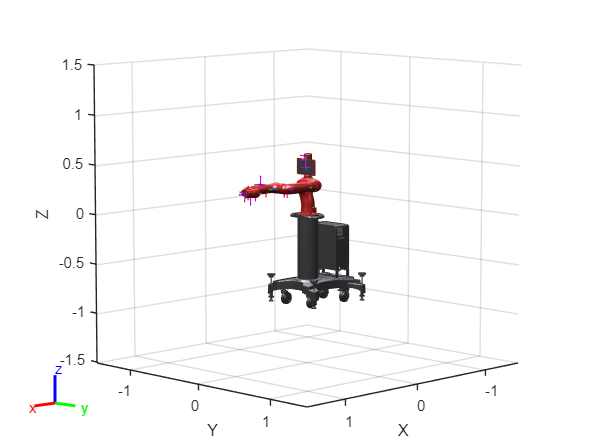

sim = robot_kinematic_sim_sawyer();


q = sim.robot.randomConfiguration()

q =     0.8717
   -3.8410
   -0.0525
    1.0692
    0.6165
   -0.9173
   -0.8093
   -3.0949


q = [q(1);q(3:end)]

q =     0.8717
   -0.0525
    1.0692
    0.6165
   -0.9173
   -0.8093
   -3.0949


sim.set_q(q)

sim.fwd_kin()
sim.fwd_kin_sew()

ans = -1.0366

T = sim.xyz

T =     0.1925
    0.9646
    0.1943


R = quat2rotm(sim.quat)

R =    -0.9604   -0.0663    0.2706
    0.2636   -0.5304    0.8057
    0.0902    0.8451    0.5269


psi = sim.sew_stereo

psi = -1.2564

GC = sim.GC

GC =     -1     1    -1



SEW_type ="Stereographic";

qq = closed_form_inv_kin(R, T, SEW_type, psi, GC, sim.kin_approx)

d_S_E = 0.5181

d_E_W = 0.4013

qq =     0.9076
    0.0300
    1.0118
    0.7402
   -0.8264
   -0.9950
    3.0601


rad2deg(wrapToPi(q -qq))

ans =    -2.0551
   -4.7290
    3.2858
   -7.0866
   -5.2094
   10.6372
    7.3418


[fk.R_T, fk.p_T, fk.p_E, fk.p_W, fk.J_T, fk.J_E, fk.J_W]  = fwd_kin_diff_with_SEW(sim.kin_approx, qq);
tf_EE = getTransform(rob_approx, qq,'end_effector')

tf_EE =    -0.9604   -0.0663    0.2706    0.1925
    0.2636   -0.5304    0.8057    0.9646
    0.0902    0.8451    0.5269    0.1943
         0         0         0    1.0000


tf_E = getTransform(rob_approx, qq,'body_4')

tf_E =    -0.0028   -0.4022    0.9155    0.1443
    0.9251    0.3466    0.1551    0.4974
   -0.3797    0.8474    0.3711    0.3026
         0         0         0    1.0000


%tf_W = getTransform(sim.robot, [q(1); 0; q(2:end)],sim.body_names.W)

[q_iter, stop_condition, err_hist] = iter_IK(R, T, psi, qq, sim.kin, SEW_type, sim.V_conv, sim.R_stereo, sim.V_stereo, sim.p_S);
disp(stop_condition)

Error below MAX_ERR


q_iter

q_iter =     0.8716
   -0.0525
    1.0695
    0.6167
   -0.9175
   -0.8093
    3.1881


rad2deg(wrapToPi(q -q_iter))

ans =     0.0093
   -0.0016
   -0.0184
   -0.0110
    0.0120
   -0.0026
    0.0086



sign(wrapToPi([q(2) q(4) q(6)]))

ans =     -1     1    -1


sign(wrapToPi([q_iter(2) q_iter(4) q_iter(6)]))

ans =     -1     1    -1


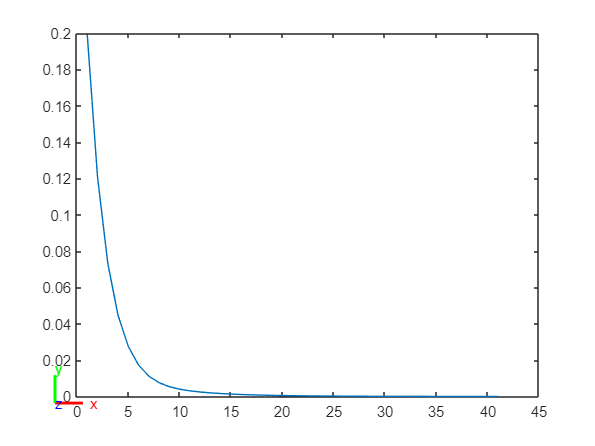


err_hist = err_hist(:,~isnan(sum(err_hist)));
plot(vecnorm(err_hist))

[fk.R_T, fk.p_T, fk.p_E, fk.p_W, fk.J_T, fk.J_E, fk.J_W]  = fwd_kin_diff_with_SEW(sim.kin, q_iter);

rob_approx = kin2robot(sim.kin_approx);

show(sim.robot, [q(1); 0; q(2:end)])

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
show(sim.robot, [q_iter(1); 0; q_iter(2:end)])

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


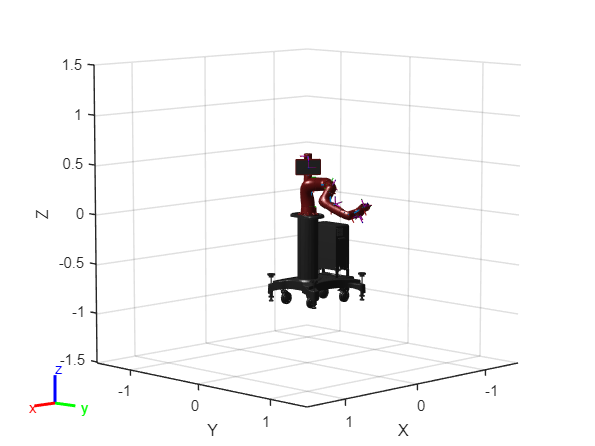

%show(rob_approx,qq)
hold off

rob_approx = kin2robot(sim.kin_approx);

show(sim.robot,'Visuals','off')
hold on
show(rob_approx)
hold off

% Compare SEW angles

[fk.R_T, fk.p_T, fk.p_E, fk.p_W, fk.J_T, fk.J_E, fk.J_W]  = fwd_kin_diff_with_SEW(sim.kin, q);
[fk2.R_T, fk2.p_T, fk2.p_E, fk2.p_W, fk2.J_T, fk2.J_E, fk2.J_W]  = fwd_kin_diff_with_SEW(sim.kin, q_iter);

stereo_sew(sim.p_S, fk.p_E, fk.p_W, sim.R_stereo, sim.V_stereo)

ans = -1.2569

stereo_sew(sim.p_S, fk2.p_E, fk2.p_W, sim.R_stereo, sim.V_stereo)

ans = -1.2564